# IDENTIFICACION DEL MODELO ARX

clear all
close all

datos = xlsread("../data_prbs.csv");
%datos = xlsread("../data_step.csv");
% datos = xlsread("Datos_Modelo_ARX.xlsx");
prbs = true;

t = datos(:,1);
Y = datos(:,2);
U = datos(:,3)*10;

subplot(2,1,1)
plot(t,U,'*','MarkerSize',4)
ylabel('Entrada')
xlabel('Muestras')
grid on

subplot(2,1,2)
plot(t,Y,'r','MarkerSize',4)
ylabel('Salida')
xlabel('Muestras')
grid on
hold on

% Se selecciona na = 3, nb = 2, d = 3
% CONDICION OBLIGATORIA: 
% b <= a !!!
na = 1;
nb = 0;
d = 1;
N = length(Y);
X = zeros(N+1,na+nb+1);
X_i = zeros(N+1,na+nb+1);
for i=[1:N+1]
    for j=[1:na]
        X_i(i,j) = (i-2) - (j-1);
    end
    for j=[na+1:na+nb+1]
        X_i(i,j) = (i-2) - (j-(na+1)-1) - d;
    end
end
for i=[1:N+1]
    for j=[1:na]
        if(X_i(i,j) >= 0)
            X(i,j) = -Y(1 + X_i(i,j));
        else
            X(i,j) = 0;
        end
    end
    for j=[na+1:na+nb+1]
        if(X_i(i,j) >= 0)
            X(i,j) = U(1 + X_i(i,j));
        else
            X(i,j) = 0;
        end
    end
end
X = X(1:end-1,:);

Q = X'*X;
theta = inv(Q) * X' * Y;
a = zeros(1,na);
for i = [1:na]
    a(i) = theta(i);
end
b = zeros(1,nb+1);
for i = [1:nb+1]
    b(i) = theta(i+na);
end

T = t(2) - t(1);
z = tf('z',T);

z_num = 0;
z_den = 1;
for i=[0:1:nb]
    z_num = z_num + b(i+1)*z^-i;
end
for i=[1:1:na]
    z_den = z_den + a(i)*z^-i;
end

% Gpz = (0.006358*z^3 - 0.002533*z^2 - 0.001053*z + 0.001769) / (z^4 - 0.2867*z^3 - 0.3163*z^2 - 0.1212*z)
%Gpz = minreal(z_num / z_den)
Gpz = minreal((z^(-d)) * z_num / z_den)

Gpz =
 
   0.00481
  ----------
  z - 0.6888
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


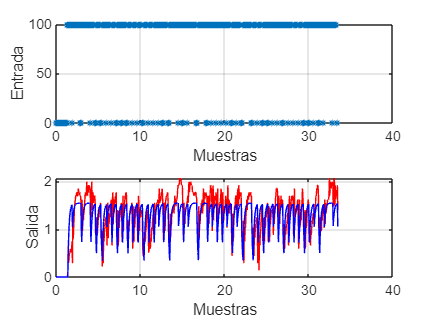

%Gpz = (0.002958*z^3 - 0.0001797*z^2 + 0.001676*z - 0.001644) / (z^4 - 0.3594*z^3 - 0.305*z^2 - 0.2046*z);

Ymodel = step(Gpz*100,'k', t(end));
if prbs
    ys = lsim(Gpz, U, t);
    plot(t,ys, 'b');
    Sr = sum((Y-ys).^2);
else
    step(Gpz*100, 'b', t(end))
    Sr = sum((Y-Ymodel).^2);
end


% Coeficiente de correlacion
Sy = sum((Y-mean(Y)).^2);
R2 = (Sy-Sr)/Sy

R2 = 0.5876